# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 26-Nov-2024 16:58:13

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 14);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "LE", "F4", "C4", "P4", "P3", "C3", "F3", "Trigger", "Time_Offset", "ADC_Status", "ADC_Sequence", "Event", "Comments"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "char"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Comments", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Comments", "EmptyFieldRule", "auto");

% Import the data
WFR2 = readtable("/Users/gayatrimalladi/Desktop/untitled folder/Prof_Mat_pre_stroke/W_F_R_2.txt", opts)

WFR2 = 18860×14 table
     Time      LE        F4       C4      P4       P3       C3        F3       Trigger    Time_Offset    ADC_Status    ADC_Sequence    Event      Comments  
    ______    _____    ______    ____    _____    _____    _____    _______    _______    ___________    __________    ____________    _____    ____________

       NaN      NaN       NaN     NaN      NaN      NaN      NaN        NaN      NaN          NaN           NaN            NaN          NaN     {'Comments'}
    0.0033    -54.1     116.3 

## Clear temporary variables

clear opts
clear opts
% Extract EEG channels
eeg_channels = WFR2{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};

% Check for NaN or Inf in the EEG channels
if any(~isfinite(eeg_channels(:)))
    eeg_channels(~isfinite(eeg_channels)) = 0; % Replace non-finite values with zeros
end

% Define sampling frequency and channel names
sfreq = 300; % Sampling frequency in Hz
ch_names = {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}; % Channel names

% Apply notch filter to remove powerline noise
notch_freqs = [50, 60]; % Frequencies to remove
for i = 1:length(notch_freqs)
    d = designfilt('bandstopiir', 'FilterOrder', 2, ...
        'HalfPowerFrequency1', notch_freqs(i) - 1, ...
        'HalfPowerFrequency2', notch_freqs(i) + 1, ...
        'SampleRate', sfreq);
    eeg_channels = filtfilt(d, eeg_channels); % Apply filter
end

% Define bandpass filter parameters
low_freq = 7;  % Lower cutoff frequency (Hz)
high_freq = 14; % Upper cutoff frequency (Hz)

% Design a bandpass filter
[b, a] = butter(4, [low_freq high_freq] / (sfreq / 2), 'bandpass');

% Apply the bandpass filter to the EEG data
filtered_data = filtfilt(b, a, eeg_channels);

% Display a summary of the filtered data
disp('Filtered EEG data:');

Filtered EEG data:


disp(filtered_data);

    0.6832    0.0019    0.6853   -1.3885    1.3891    1.1426   -0.7058
   30.4016  -55.0421    0.3107   28.1058   26.2441   25.9048 -128.1509
   58.5857 -107.1814   -0.0149   56.0917   49.7760   49.3425 -248.9028
   83.8379 -153.8353   -0.2803   81.1772   70.8282   70.2814 -356.9854
  104.9319 -192.7509   -0.4820  102.1443   88.3886   87.6934 -447.1770
  120.8825 -222.1323   -0.6232  118.0198  101.6476  100.7564 -515.3085
  130.9999 -240.7382   -0.7141  128.1282  110.0413  108.8990 -558.4906
  134.9239 -247.9427   -0.7697  132.1256  113.2795  111.8306 -575.2561
  132.6370 -243.7561   -0.8086  130.0111  111.3559  109.5512 -565.6089
  124.4559 -228.8048   -0.8507  122.1166  104.5400  102.3444 -530.9788
  111.0023 -204.2724   -0.9143  109.0760   93.3521   90.7520 -474.0884
   93.1558 -171.8088   -1.0145   91.7758   78.5244   75.5333 -398.7432
   71.9926 -133.4130   -1.1608   71.2919   60.9492   57.6127 -309.5622
   48.7150  -91.2990   -1.3556   48.8177   41.6207   38.0182 -211.6694
   24.


% Compute statistics
stats.mean = mean(eeg_channels, 1); % Mean
stats.variance = var(eeg_channels, 0, 1); % Variance
stats.std_dev = std(eeg_channels, 0, 1); % Standard Deviation
stats.median = median(eeg_channels, 1); % Median
stats.min = min(eeg_channels, [], 1); % Minimum
stats.max = max(eeg_channels, [], 1); % Maximum

% Display statistics
disp('Statistics for EEG Channels:');

Statistics for EEG Channels:


disp(array2table([stats.mean; stats.variance; stats.std_dev; stats.median; stats.min; stats.max], ...
    'VariableNames', ["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
    'RowNames', {'Mean', 'Variance', 'StdDev', 'Median', 'Min', 'Max'}));

                  LE         F4         C4          P4          P3          C3          F3   
                _______    _______    _______    ________    ________    ________    ________

    Mean         1.0047    -6.8503     1.6773     0.80863     0.11174    -0.24791     -3.6616
    Variance     206.13      627.4     312.44      269.57      122.68      141.87      2593.7
    StdDev       14.357     25.048     17.676      16.419      11.076      11.911      50.929
    Median      0.63294    -4.1933    0.55158    -0.07397    -0.26522     -0.7388    -0.45041
    Min         -58.128    -642.26    -71.297     -54.642     -33.646     -41.803     -1489.4
    Max   

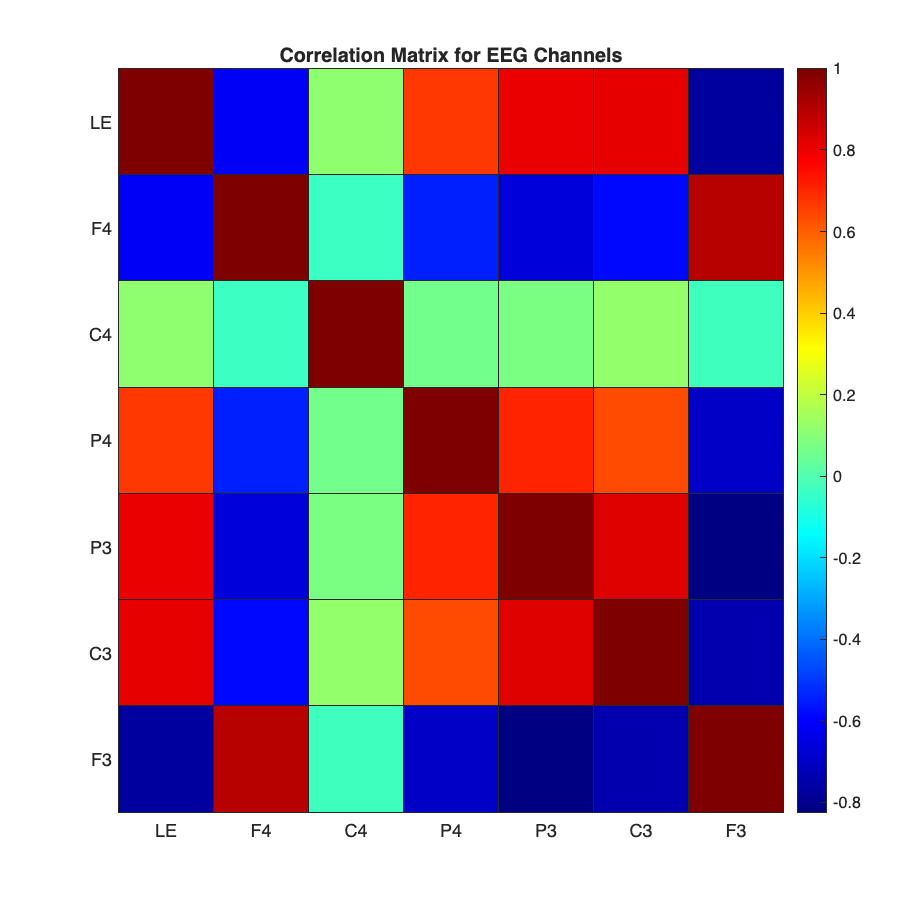


% Compute the correlation matrix
correlation_matrix = corr(eeg_channels);

% Plot correlation matrix as heatmap
figure('Name', 'EEG Correlation Matrix', 'Position', [100, 100, 800, 800]);
heatmap(["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
        ["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
        correlation_matrix, ...
        'Colormap', jet, ...
        'ColorbarVisible', 'on', ...
        'CellLabelColor', 'none'); % Optional to hide correlation labels
title('Correlation Matrix for EEG Channels');

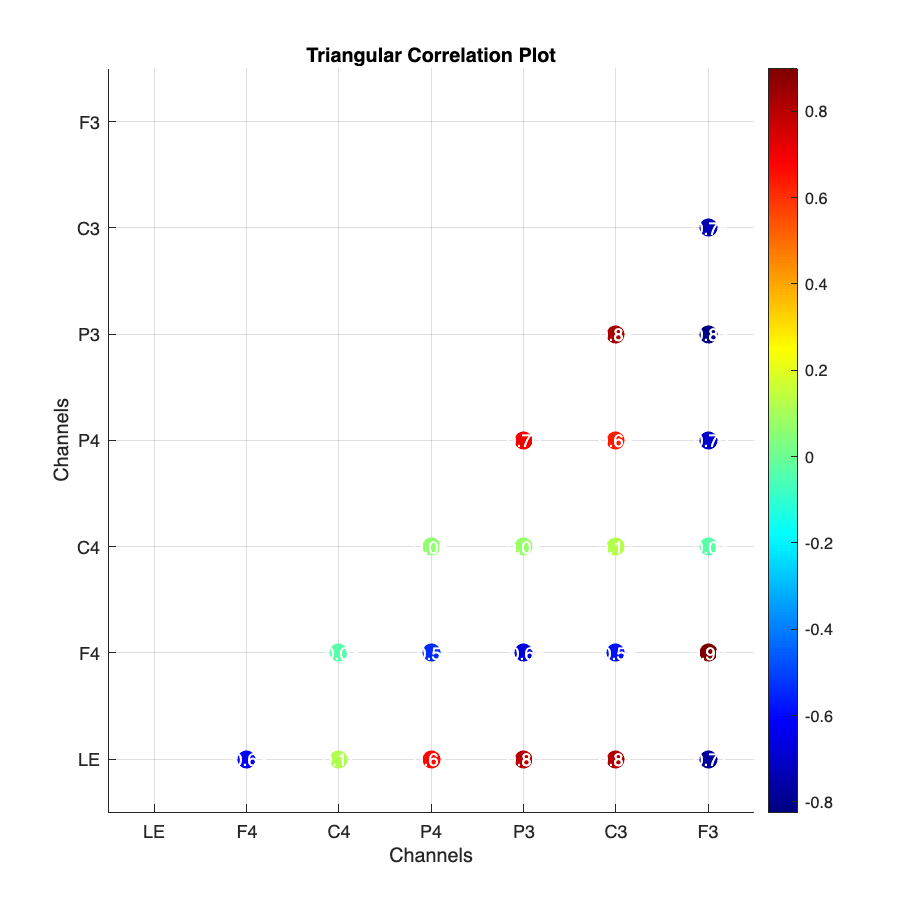


% Generate correlation plot
figure('Name', 'Triangular Correlation Plot', 'Position', [100, 100, 800, 800]);
hold on;
n_channels = size(correlation_matrix, 1);
for i = 1:n_channels
    for j = 1:i
        if i ~= j
            scatter(i, j, 100, correlation_matrix(i, j), 'filled');
            text(i, j, sprintf('%.2f', correlation_matrix(i, j)), ...
                'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'w');
        end
    end
end
colormap(jet);
colorbar;
xlim([0.5, n_channels + 0.5]);
ylim([0.5, n_channels + 0.5]);
xticks(1:n_channels);
yticks(1:n_channels);
xticklabels(["LE", "F4", "C4", "P4", "P3", "C3", "F3"]);
yticklabels(["LE", "F4", "C4", "P4", "P3", "C3", "F3"]);
xlabel('Channels');
ylabel('Channels');
title('Triangular Correlation Plot');
grid on;
hold off;

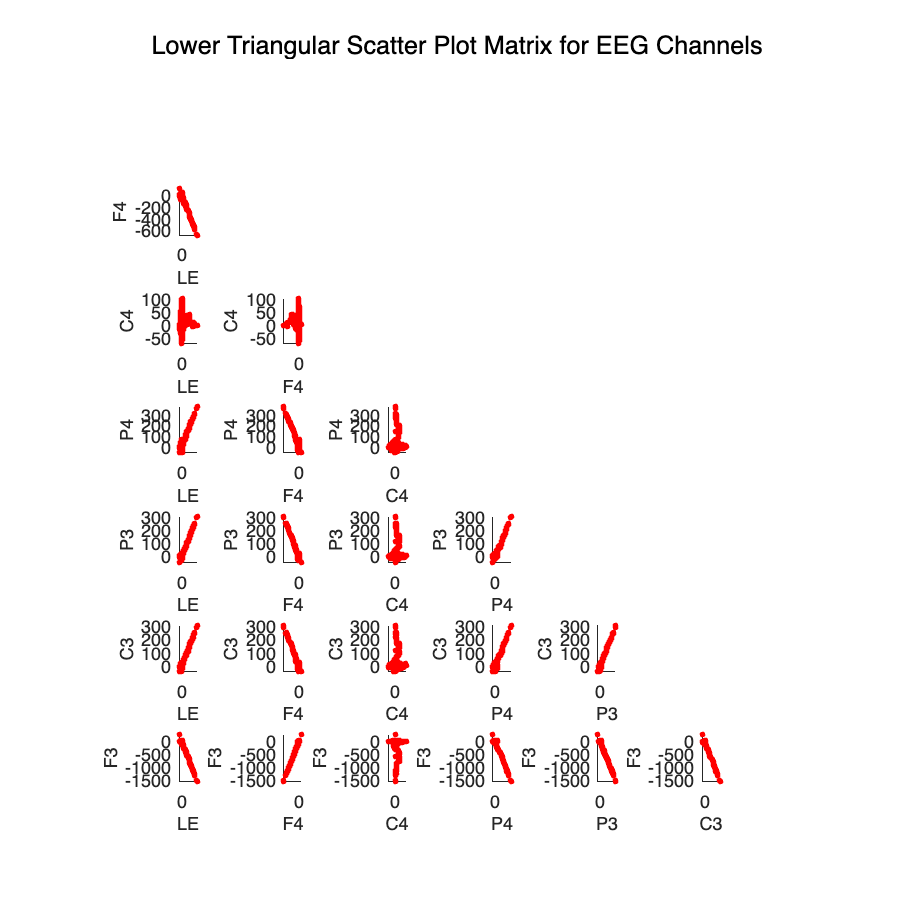

% Extract relevant variables from WaveFistRub1
eeg_channels = WFR2{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};
channel_names = ["LE", "F4", "C4", "P4", "P3", "C3", "F3"];
num_channels = size(eeg_channels, 2);

% Create figure for scatter plot matrix
figure('Name', 'Scatter Plot Matrix for EEG-1 Channels', 'Position', [100, 100, 1000, 1000]);

for i = 2:num_channels
    for j = 1:i-1
        % Plot the scatter plot with red dots
        subplot(num_channels, num_channels, (i-1) * num_channels + j);
        scatter(eeg_channels(:, j), eeg_channels(:, i), 10, 'r', 'filled'); % Red color for dots
        xlabel(channel_names(j), 'FontSize', 10);
        ylabel(channel_names(i), 'FontSize', 10);
        xlim([min(eeg_channels(:, j)) max(eeg_channels(:, j))]);
        ylim([min(eeg_channels(:, i)) max(eeg_channels(:, i))]);
    end
end

% Remove upper triangle subplots to create lower triangular matrix
for i = 1:num_channels
    for j = i:num_channels
        subplot(num_channels, num_channels, (i-1) * num_channels + j);
        axis off;
    end
end

% Title for the scatter plot matrix
sgtitle('Lower Triangular Scatter Plot Matrix for EEG Channels', 'FontSize', 14);


% Read additional data from another file
data = readtable("/Users/gayatrimalladi/Desktop/untitled folder/Prof_Mat_pre_stroke/W_F_R_2.txt"); 

% Extract EEG channels and time from the new data
eeg_channels = data{:, {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}};
time = data{:, 'Time'};


% Extract EEG channels
eeg_channels = WFR2{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};
% 1. Zero Crossing Rate
zero_crossing_rate = sum(diff(sign(eeg_channels)) ~= 0, 1) / size(eeg_channels, 1);
disp(zero_crossing_rate)

    0.1138    0.0689    0.0532    0.0785    0.0939    0.1263    0.0991




% 2. Skewness
skewness_val = skewness(eeg_channels, 0, 1);
disp(skewness_val)

   10.2511  -11.9464    0.8590    7.4761   12.5735   10.2295  -18.0485




% 3. Kurtosis
kurtosis_val = kurtosis(eeg_channels, 0, 1);
disp(kurtosis_val)

  182.2254  220.9413    6.5146  116.9429  243.1260  181.5209  386.3303



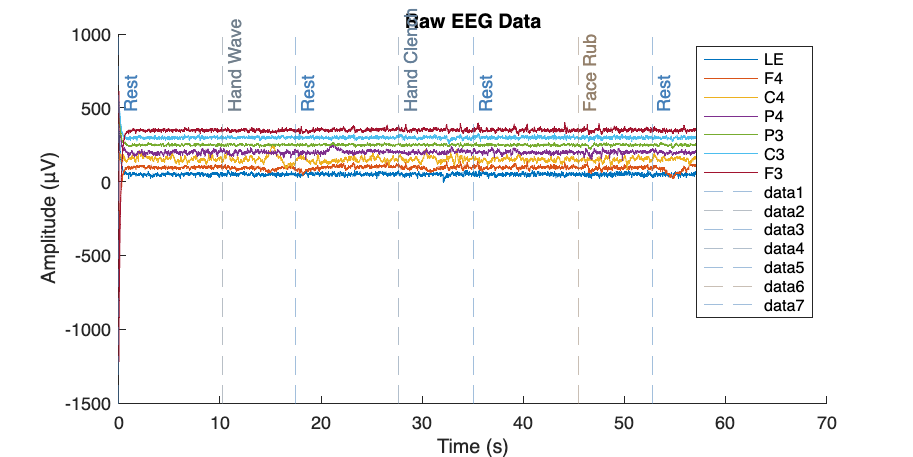

% Extract relevant data
time = data.Time; 
comments = data.Comments; 
eeg_channels = data{:, {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}}; % EEG channels
ch_names = {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}; % Channel names
sfreq = 300; % Sampling frequency
% Step 1: Parse comments and timestamps
comment_timestamps = [];
comment_names = {};
for i = 1:height(data)
    if ischar(data.Comments{i}) && ~isempty(strtrim(data.Comments{i}))
        comment_timestamps(end+1) = data.Time(i); % Add timestamp
        comment_names{end+1} = data.Comments{i}; % Add comment
    end
end
% Step 2: Generate a color for each comment
hash = @(str) mod(sum(double(str) .* (1:length(str))), 256); % Simple hash function
name_to_color = @(name) [hash(name)/255, 0.5, 1 - hash(name)/255]; % Generate RGB colors
% Step 3: Plot raw EEG data
figure('Name', 'Raw EEG Data', 'Position', [100, 100, 1000, 500]);
colors = lines(length(ch_names)); % Define colors for channels

hold on;
for i = 1:size(eeg_channels, 2)
    plot(time, eeg_channels(:, i) + i * 50, 'Color', colors(i, :), 'DisplayName', ch_names{i}); % Offset each channel for clarity
end
% Add vertical lines and labels for comments
for i = 1:length(comment_timestamps)
    comment_color = name_to_color(comment_names{i});
    xline(comment_timestamps(i), '--', 'Color', comment_color, 'Alpha', 0.5);
    text(comment_timestamps(i), max(max(eeg_channels)) + 100, comment_names{i}, ...
        'Rotation', 90, 'VerticalAlignment', 'top', 'Color', comment_color);
end

title('Raw EEG Data');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
legend('show');
hold off;

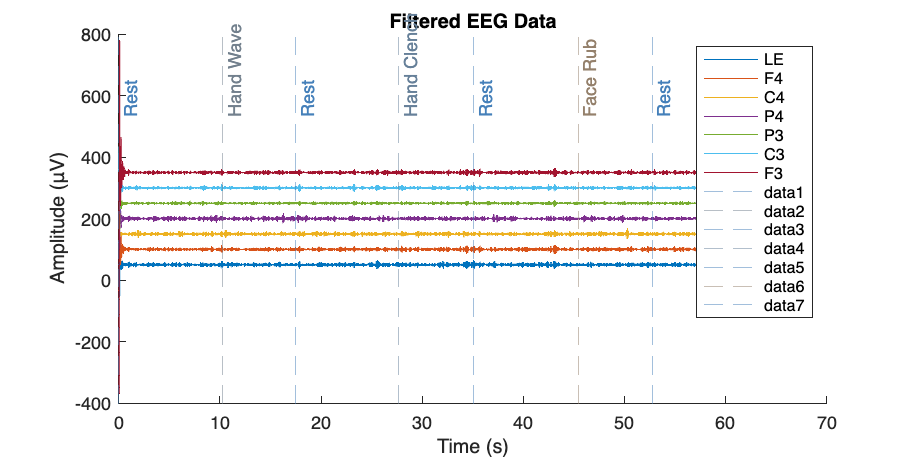

% Step 4: Apply filters (notch and bandpass)
notch_freqs = [50, 60];
for f = notch_freqs
    d = designfilt('bandstopiir', 'FilterOrder', 2, ...
        'HalfPowerFrequency1', f - 1, ...
        'HalfPowerFrequency2', f + 1, ...
        'SampleRate', sfreq);
    eeg_channels = filtfilt(d, eeg_channels); % Apply notch filter
end
% Bandpass filter
low_freq = 7; high_freq = 14;
[b, a] = butter(4, [low_freq high_freq] / (sfreq / 2), 'bandpass');
filtered_data = filtfilt(b, a, eeg_channels);
% Step 5: Plot filtered EEG data
figure('Name', 'Filtered EEG Data', 'Position', [100, 100, 1000, 500]);
hold on;
for i = 1:size(filtered_data, 2)
    plot(time, filtered_data(:, i) + i * 50, 'Color', colors(i, :), 'DisplayName', ch_names{i}); % Offset each channel
end
% Add vertical lines and labels for comments
for i = 1:length(comment_timestamps)
    comment_color = name_to_color(comment_names{i});
    xline(comment_timestamps(i), '--', 'Color', comment_color, 'Alpha', 0.5);
    text(comment_timestamps(i), max(max(filtered_data)) + 100, comment_names{i}, ...
        'Rotation', 90, 'VerticalAlignment', 'top', 'Color', comment_color);
end
title('Filtered EEG Data');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
legend('show');
hold off;

% Step 6: Time-frequency analysis using wavelet transform
frequencies = 1:80; % Frequencies of interest
n_cycles = frequencies / 2; % Number of cycles in the wavelet
time_range = 1:length(time) / sfreq;
% Morlet wavelet analysis
[power_raw, ~] = cwt(eeg_channels(:, 1), sfreq, 'FrequencyLimits', [min(frequencies) max(frequencies)]); % Example on channel 1
[power_filtered, ~] = cwt(filtered_data(:, 1), sfreq, 'FrequencyLimits', [min(frequencies) max(frequencies)]); % Example on channel 1
% Plot time-frequency analysis for raw data
figure('Name', 'Time-Frequency Analysis (Raw)', 'Position', [100, 100, 1000, 500]);
